% Load the data/variables from the file named spirometer.txt
spiro = load("spirometer.txt")

spiro =   -370
  -369
  -367
  -366
  -364
  -362
  -361
  -359
  -357
  -355



% Resample the spirometer data into 50 Hz
spiro_resampled = resample(spiro, 50, 100)

spiro_resampled =  -277.4121
 -392.1251
 -351.3696
 -368.5630
 -352.2934
 -356.0149
 -345.9610
 -343.2728
 -335.5871
 -329.4594


% Load the belt data into Nx2 matrix from the file beltsignals.txt
belt = load("beltsignals.txt")

belt =    116   452
   113   440
   110   425
   106   410
   103   394
   100   377
    97   360
    93   343
    90   326
    86   309


% Load the regression coefficients vector for the models 1-3
coeff1 = load("regressioncoefficients1.txt")

coeff1 =     0.9093
   -1.2707


coeff2 = load("regressioncoefficients2.txt")

coeff2 =     0.2280
   -1.0976
    0.0024
    0.0001


coeff3 = load("regressioncoefficients3.txt")

coeff3 =     0.2371
   -1.0991
    0.0012


% Predict the airflow using the models
flow1 = sum(coeff1.'.*belt, 2)

flow1 =  -468.8760
 -456.3556
 -440.0231
 -424.5998
 -406.9966
 -388.1227
 -369.2488
 -351.2841
 -332.4102
 -314.4456


flow2 = sum(coeff2.'.*cat(2,belt,belt.*belt), 2)

flow2 =  -411.5784
 -402.0915
 -389.5580
 -377.6600
 -363.9148
 -349.0600
 -334.0887
 -319.6746
 -304.4561
 -289.7614


flow3 = sum(coeff3.'.*cat(2,belt,prod(belt, 2)), 2)

flow3 =  -408.6751
 -399.3319
 -386.9898
 -375.2546
 -361.7070
 -347.0650
 -332.3051
 -318.0609
 -303.0456
 -288.5067


corr1 = corr(flow1, spiro_resampled)

corr1 = 0.9570

corr2 = corr(flow2, spiro_resampled)

corr2 = 0.9464

corr3 = corr(flow3, spiro_resampled)

corr3 = 0.9454


rmse1 = sqrt(mean(mean((spiro_resampled - flow1).^2)))

rmse1 = 110.2165

rmse2 = sqrt(mean(mean((spiro_resampled - flow2).^2)))

rmse2 = 129.1058

rmse3 = sqrt(mean(mean((spiro_resampled - flow3).^2)))

rmse3 = 130.1428

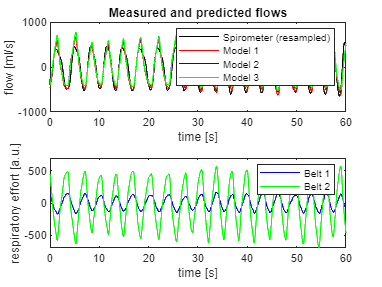

visualize_regression(spiro_resampled, belt,flow1, flow2, flow3)